# Business Analytics - Homework

## Author: Luca Laiolo, 338344

The goal of the homework was to build an object-oriented library for **Discrete Event Simulation. **

The library is mainly composed by 5 classes, namely:

- `SimulationEngine`

- `event`

- `state`

- `futureEventsList`

- `statsManager`

addpath("MATDES\")
addpath("MATDES\Statistics\")
addpath("Manifacturing Example\")

The logic behind discrete event simulation can be summarized in the figure below, taken from [1]. 

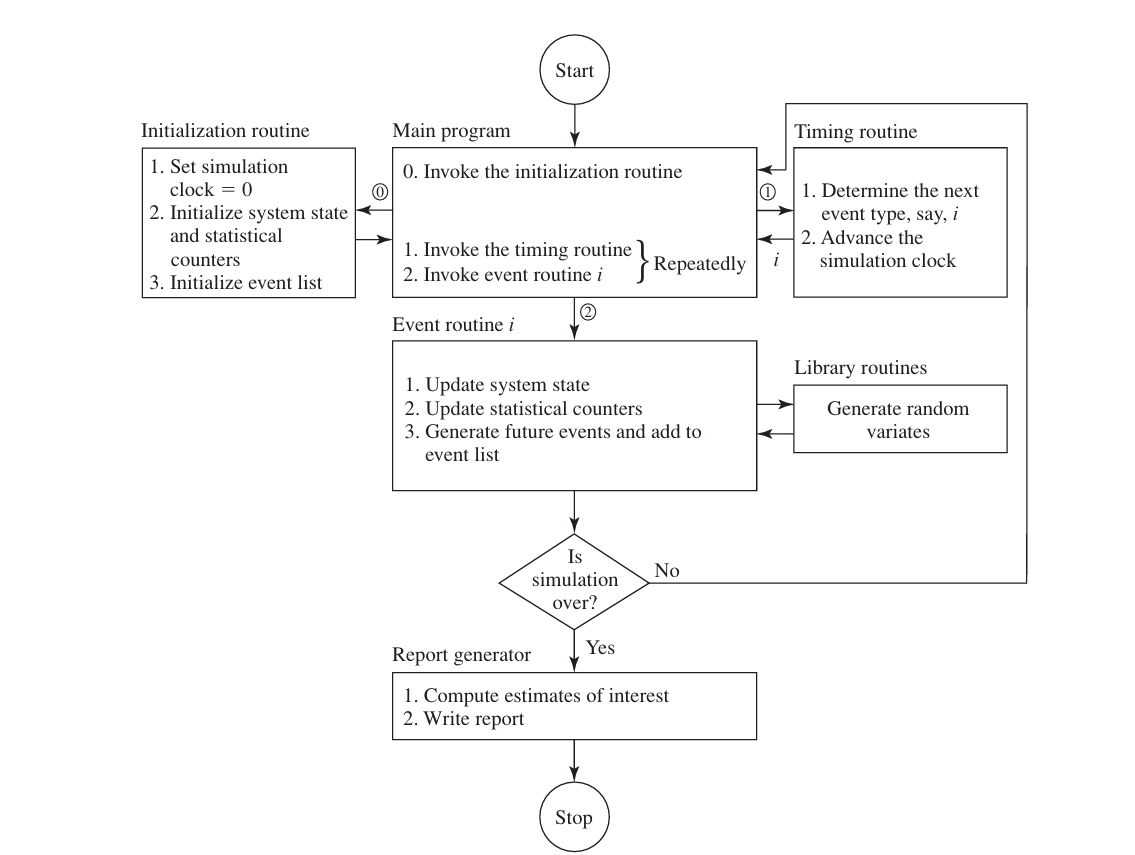

`SimulationEngine`

The `SimulationEngine` class (subclass of `handle`) defines a framework for discrete event simulation. In particular, the simulation we will run will be instances of this class. 

The properties of the `SimulationEngine` class are the following:

- `state`, a `state` object. This will represent the state of the system we want to simulate;

- `clock`, the simulation clock;

- `eventsList`, a `futureEventsList` object. It will contain the scheduled future events.

- `stats`, a `statsManager` object. It will be used to track some statistics during the simulation run.

The constructor for this class relies on the constructors for `state, futureEventsList` and `statsManager`. The syntax is the following:

The state will be initialized using the argument `stateStruct`. On the other hand, `stats` (which is an instance of the `statsManager` class) will be initialized using the argument `statStruct.` The idea is to track some quantities specified in `statStruct`. In particular, the field names will correspond to the quantity we want to track and the corresponding value will be a subclass of the `Statistic` class (more on this below).

The methods (other than the constructor) provided by this class are the following:

- `initEventsList`, which initializes the `futureEventsList` property. In particular, this methods takes as input an array of `event` objects. This method **must** be called before starting the simulation run. If this is not the case, the simulation will start with an empty `futureEventsList` and an error will occur.

- `terminationCondition`, which returns a flag that indicates whether the simulation must stop or not. This method is abstract (since different simulations may have very different stopping conditions) and takes as input `stoppingParameters`, useful to define stopping conditions that depend on some parameters.

- `run`, which runs the simulation. This method takes `stoppingParameters` as the only argument.

- `clear`, which clears the state, the statistical counters and sets the simulation clock to zero. Specifically, this method takes as input `DataStruct`, a struct used to update the state to the desired default value.

- `generateReport`, which prints a summary of the statistics collected during the simulation run. This method does not take arguments.

#### `event`

The `event` class is the core of discrete event simulation. It is defined as a subclass of `handle` and `matlab.mixin.Heterogeneous`. From the documentation, `matlab.mixin.Heterogeneous` is an abstract class that supports forming heterogeneous arrays. A heterogeneous array is an array of objects that differ in their specific class, but are all derived from or are instances of a root class. The root class derives directly from `matlab.mixin.Heterogeneous`. This choice was made for a clear reason: we would like to build arrays of specific events which are subclasses of the `event` class.

The properties of this class are the following:

- `label`, which is a string that represents the kind of event we are modelling.

- `parameters`, which is (typically) a row (or column) vector containing the parameters necessary to generate random variables.

- `clock`, which is the event clock.

The constructor for this class is the obvious one, setting the properties to the desired values.

As far as the other methods are concerned, only abstract methods are defined. Specifically, the methods defined are:

- `rnd`, which returns a random variable from some distribution using the parameters defined in `parameters`.

- `manageEvent`, which takes as input a `SimulationEngine` object and updates it.

To run a specific simulation, we will need to define these two methods for every type of event that can occur during the simulation run.

`state`

The `state` class will represent the state of the system we are simulating. It is defined as a subclass of the `dynamicprops` class, which is in turn a class derived from the `handle` class. The reason for this is quite simple: we want to define the properties when we actually build the `state` object. In particular, with the following syntax

we instantiate a `state` object whose properties (and the corresponding values) are defined by the struct `DataStruct`. 

Other than the constructor, this class provides only one method, which is `update`. This method takes as inputs two row cell arrays, which correspond to the properties we want to update and the corresponding new values. This method can be used to clear the state, too (provided that the passed argument is the desired default value).

For example,

DataStruct = struct( ...
    'A', zeros(10,10), ...
    'B', zeros(10,1), ...
    'C', 0);
s = state(DataStruct)

s =   state with properties:

    B: [10×1 double]
    A: [10×10 double]
    C: 0


`futureEventsList`

The `futureEventsList` class is a handle class which implements a priority queue to manage an array of `event` objects (actually, subclasses of the `event` superclass). The priority queue is implemented using a binary heap. This allows the `Enqueue` and `Dequeue` operations to be performed with a complexity of $\mathcal{O}(logn)$, where $n
$ is the number of elements inside the heap. The implementation corresponds to the one presented in [2].

The methods provided by this class do not differ by the methods provided by a basic priority queue (namely, `Enqueue`, `Dequeue`, `First`, `Empty`). The priority of an event is simply its simulation clock, so that the earliest event is always the one that is dequeued first. No secondary criterion was considered in the case of two events with the same clock.

`statsManager`

The `statsManager` class is a handle class responsible of collecting some desired statistics during the simulation run. 

The properties of this class are the following:

- `statistics`, a struct whose fields correspond to the quantities we are tracking and the corresponding values are subclasses of the `Statistic` class. The `Statistic` class is an abstract class with no pre-defined properties and with three abstract methods: `update`, `clear`, `getResult`. This choice was made in order to make the implementation as modular as possible. In fact, the statistics that we might want to collect may be of very different nature. Some possible subclasses of the `Statistic` class have been implemented, namely `CountStatistic`, `SumStatistic`, `AverageStatistic`, `TimeAverageStatistic`. 

- `clock`, the simulation clock.

The constructor for this class is quite basic. With this syntax

we are creating a `statsManager` object whose `statistics` properties is initialized using `statStruct`. For example,

statStruct = struct( ...
    'numInQueue', SumStatistic, ...
    'average_queue_length', TimeAverageStatistic);
myStatsManager = statsManager(statStruct)

myStatsManager =   statsManager with properties:

    statistics: [1×1 struct]
         clock: 0


myStatsManager.statistics

ans = struct with fields:
              numInQueue: [1×1 SumStatistic]
    average_queue_length: [1×1 TimeAverageStatistic]


myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 0
         totalTime: 0
    lastUpdateTime: 0


Other than the constructor, only two methods are provided: `update` and `clear`. Both of these methods rely on the respective `update` and `clear` methods for the `Statistic` subclasses.

For example,

myStatsManager.update('numInQueue', 10);
myStatsManager.statistics.numInQueue

ans =   SumStatistic with properties:

    sum: 10


myStatsManager.clock = 10;
myStatsManager.update('average_queue_length', 5)
myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 50
         totalTime: 10
    lastUpdateTime: 10


**Important:** when we update a `TimeAverageStatistic` object, we must provide the **old** value, not the new.

myStatsManager.clear()
myStatsManager.statistics.numInQueue

ans =   SumStatistic with properties:

    sum: 0


myStatsManager.statistics.average_queue_length

ans =   TimeAverageStatistic with properties:

       weightedSum: 0
         totalTime: 0
    lastUpdateTime: 0


#### A (simple) example (1.22 from [1])

A manufacturing system contains $m$ machines, each subject to randomly occuring breakdowns. A machine runs for an amount of time that is an exponential random variable with mean 8 hours before breaking down. There are $s$ (where $s$ is a fixed, positive integer) repairmen to fix broken machines, and it takes one repairman an exponential amount of time with mean 2 hours to complete the repair of one machine; no more than one repairman can be assigned to work on a broken machine even if there are other idle repairmen. If more than $s$ machines are broken down at a given time, they form a FIFO "repair" queue and wait for the first available repairman. Further, a repairman works on a broken machine until it is fixed, regardless of what else is happening in the system. Assume that it costs the system $50 for each hour that each machine is broken down and $10 an hour to employ each repairman.

Simulate the system for 500 hours (basically, three weeks) for each of the employment policies $s = 1,\dots, 10$ to determine which policy results in the smallest expected average cost per hour. Assume that at time 0 all machines have just been "freshly" repaired.

numMachines =10

numMachines =     10


The code for this example can be found inside the folder `Manifacturing Example` (this could take some minutes to run). The cost could be modeled using subclass of `Statistic` too and the code would be very similar.

rng 'default'
% Data 
numWorkers = 1:10;
breakdownRate = 1/8;
repairRate = 1/2;
numHours = 500;

% Number of repetitions per configuration
numRep = 50;

% Quantities of interest
costCI = zeros(2, length(numWorkers));
numIdleCI = zeros(2, length(numWorkers));

for i=1:length(numWorkers)
    % Run the simulation
    [costCI(:,i), numIdleCI(:,i)] = ...
        runManifacturingSystem(numRep, numHours, numWorkers(i), numMachines, breakdownRate, repairRate);
end

Let's visualize the costs.

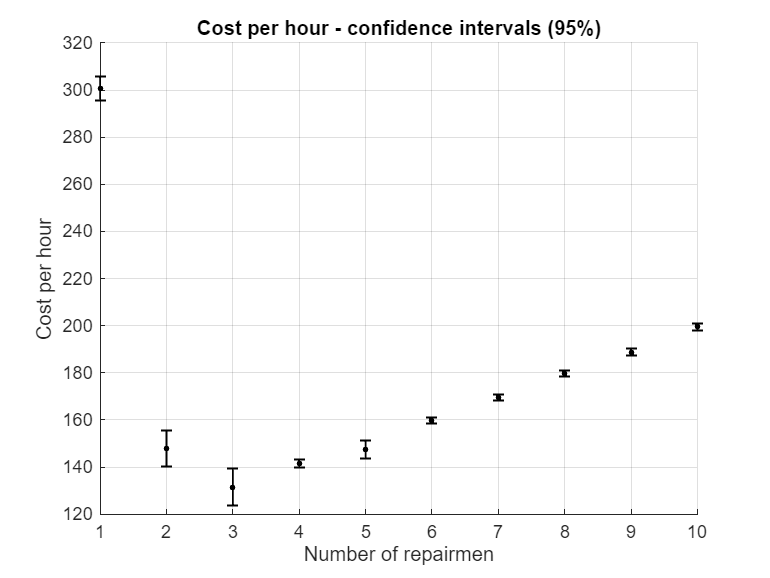

costMean = (costCI(1,:) + costCI(2,:)) / 2;
neg = costMean - costCI(1,:);
pos = costCI(2,:) - costMean;
figure;
hold on;
errorbar(numWorkers, costMean, neg, pos, 'ko', 'MarkerSize', 2, 'MarkerFaceColor', 'k', 'LineStyle', 'none', 'LineWidth', 1);
xlabel('Number of repairmen');
ylabel('Cost per hour');
title('Cost per hour - confidence intervals (95%)');
grid on;

From the plot, it looks like the optimal choice is $s = 3
$ (if the number of machines is 10). We can see that as the number of workers increases, the confidence intervals shrink around the mean point. To give an interpretation to this phenomenon, this might be the caused by the fact that having more workers simply implies that it is more unlikely that, by chance, the repair queue gets large, and hence it is unlikely that very costly breakdowns occur.

We can take a look at the mean number of idle repairmen (computed as a time average, as for the queue length, for example).

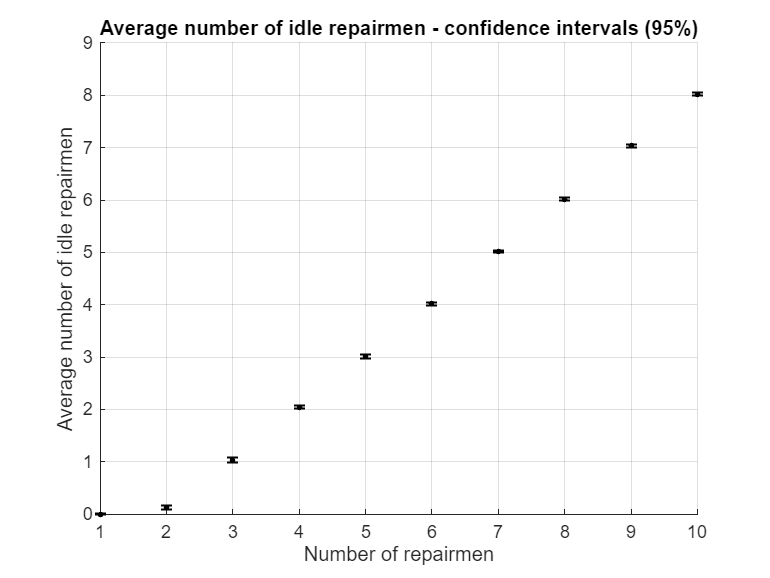

numIdleMean = (numIdleCI(1,:) + numIdleCI(2,:)) / 2;
neg = numIdleMean - numIdleCI(1,:);
pos = numIdleCI(2,:) - numIdleMean;
figure;
hold on;
errorbar(numWorkers, numIdleMean, neg, pos, 'ko', 'MarkerSize', 2, 'MarkerFaceColor', 'k', 'LineStyle', 'none', 'LineWidth', 1);
xlabel('Number of repairmen');
ylabel('Average number of idle repairmen');
title('Average number of idle repairmen - confidence intervals (95%)');
grid on;

The example considered is very simple. It seems unlikely, for example, that only one repairman is allowed to work on a broken machine. Moreover, it seems unlikely that all the repairmen have the ability to repair all the machines, requiring always the same mean amount of time. In addition, it might not be true that a repairman starts repairing another machine as soon as he is done fixing another one. To model this, we might introduce a `Break` event in which the repairman gets idle independently of the size of the repair queue.

This simple example was, however, enough to demonstrate the capabilities of the simulation library developed. Of course, by defining more complex events, more complex systems can be modelled.

#### References

[1] Averill M. Law and David M. Kelton. *Simulation Modeling and Analysis*. McGraw-Hill Higher Education, 5th edition, 2015. 

[2] P. Crescenzi et al., *Strutture di dati e algoritmi. Progettazione, analisi e visualizzazione*. Pearson, 2012